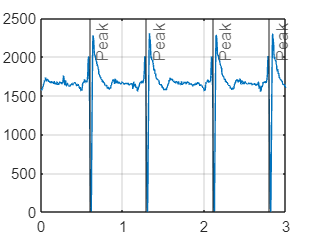

i = 151

i = 324

i = 528

i = 701

i = 905

i = 1078

i = 1282

i = 1455

i = 1659

i = 1832

i = 2036

i = 2209

i = 2413

i = 2585

i = 2587

i = 2790

i = 2962

i = 3167

i = 3339

i = 3544

i = 3716

i = 3924

i = 4096

i = 4301

i = 4473

i = 4678

i = 4850

i = 5055

i = 5227

i = 5432

i = 5604

i = 5809

i = 5981

i = 6186

i = 6358

i = 6563

i = 6734

i = 6939

i = 7110

i = 7315

i = 7487

clear
close all

T_A = 4e-3;
f_A = 1/T_A;


data = transpose(load("uC_data.mat").dataOut(:,2));
BUFFERSIZE = length(data);
t = linspace(0,30,BUFFERSIZE);
heartTime = 0;

peakDetected = false;

figure
plot(t, data)
xlim([0 3])
grid
n= 1;
for i=2:BUFFERSIZE
    if data(i) <  1000
        if(data(i) < data(i-1))
            if peakDetected == false
                i
                heartTime(:,n) = t(i); 
                xline(t(i), '-','Peak')
                peakDetected = true;
                if(n>1)
                    heartRate = heartTime(n) - heartTime(n-1);
                end
                n = n+1;
            end
        elseif data(i) > data(i-1)
            peakDetected = false;
        end
    end
end